p0=zeros(1,3);
p1=[3,5,4];
p2=[1,2,1];
p3=mirrorTransform(p1,p2)

Trans =    -0.6667    0.6667    0.3333
    0.6667    0.3333    0.6667
    0.3333    0.6667   -0.6667


映射卫星位置伪距误差： 2.6645e-15


p3 =     2.6667    6.3333    1.6667


p = [p1' p2' p3']

p =     3.0000    1.0000    2.6667
    5.0000    2.0000    6.3333
    4.0000    1.0000    1.6667


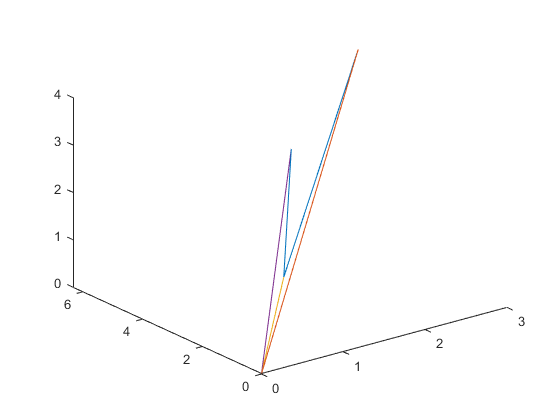

figure
plot3(p(1,:),p(2,:),p(3,:));
hold on 
plot3([0 p1(1)],[0 p1(2)],[0 p1(3)])
plot3([0 p2(1)],[0 p2(2)],[0 p2(3)])
plot3([0 p3(1)],[0 p3(2)],[0 p3(3)])
hold off


p13C = (p1+p3) ./2;
pC2 = p2- p13C;
p13 = p1 - p3;
pC2 * p13'

ans = logical
   0
